# 9. Microphones, op-amps, and spectra

5Oct24 B. R.

## Introduction to AC

These next sections are terse summaries of key theory, that will make more sense *after* studying chapters and text books written on the topics. We'll revisit them in several upcoming chapters, as we design and build filters, assemble a function generator kit, and measure amplitudes and phases of its sinusoidal output. 

### Capacitor theory

Capacitors are defined by a current-voltage relationship: $i = C\frac{dV}{dt}$, the current through them is proportional to the *rate of change* of voltage across them. Kirchhoff's voltage and current laws (KVL, KCL) thus become differential equations -- no fun to solve! A trick to getting back to solving algebraic equations is called Fourier Analysis [1]. There are special functions who's derivative is proportional to the function, i.e., $\frac{dV(t)}{dt} = \lambda V(t)$, in particular, exponential functions, $V = Ae^{\lambda t}$. Of particular interest in electronics are sinusoidal oscillating voltages, $V(t) = A \sin(\omega t + \phi)$. $\frac{dV}{dt} = \omega A \cos(\omega t + \phi) \ne \lambda V(t)$ *unless* we allow $\lambda$ to be complex (imaginary) numbers that encode the 90 degree (=$\pi/2$ radians) phase shift between sin and cos as $e^{j\pi/2}$ (in electronics we use $j=\sqrt{-1}$ -- since i = current ) [2]. Back to capacitors, if we assume the voltage across a capacitor is separable as a function of circuit parameters times a complex exponential expressing the time dependence, i.e. V(t) = V(R, C, ...)$e^{j\omega t}$ then $\frac{dV}{dt} = j\omega V$. The "impedance" (generalized resistance) of a capacitor is thus $V/i = \frac{1}{j\omega C} = \frac{1}{j2\pi f C} \equiv Z_C$. We thus avoid solving differential equations, but have to solve Ohm's Law, KVL, KCL, the voltage divider equation, with complex numbers, and also do it separately at each frequency since Zc varies with $f$. Fortunately, MATLAB knows how to do complex algebra, and we can often represent frequency (and impedances and resulting complex voltages) as vectors with components or elements representing each distinct frequency of interest.  The function `zc` implements this below -- save it in your `PATH`. 

The first line declares the file is a function with its own [namespace](https://en.wikipedia.org/wiki/Namespace). With capacitance in units of farads and frequency in hz, the returned result is in (complex) ohms.  "Pointwise division" (`./`) is used for the typical case that `hz` is an array or matrix of values. `hz` is copied to a persistent variable (that is remembered between function calls) so the shortcut, `zc1 = zc(C1, frequencies); zc2 = zc(C2);` ... works -- the second call remembered and uses the same `frequencies` as the prior one.

### Op-amp theory

When an op amp is in its linear range (i.e., not off or saturated) then it follows these two "golden rules" [3]:

- The + and - inputs are at the same voltage (Voltage Rule).

- The inputs draw no current (Current Rule).

From these we can derive the gains of two common circuit topologies, the inverting and non-inverting amplifiers. 

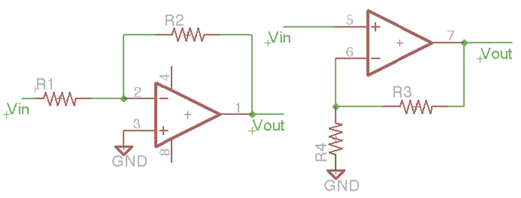

        Figure 1. Inverting (left) and noninverting (right) amplifier circuits.

Analyzing the inverting amplifier first, by the Voltage Rule, the voltage at the - input (pin 2) = GND = 0, thus the current through R1 = $i_{R1}$ = Vin/R1. (BTW, pin 2 is often referred to as a "virtual ground".) By the Current Rule and KCL, this current *must* flow through the "feedback resistor" R2, hence $i_{R2}$ = (0-Vout)/R2 = Vin/R1 = $i_{R1}$. The inner equality can be solved for the circuit gain, G $\equiv$ Vout/Vin = -R2/R1. If Vin < 0 then Vout > 0 and visa versa (assuming the op-amp doesn't saturate). When powering the op-amp with a single power supply, Vss, the + input is typically connected to a DC "bias" voltage, e.g., from a voltage divider, so the difference voltage is amplified, Vout = Vbias - R2/R1*(Vin - Vbias). The input impedance of the inverting amplifier is Zin = Vin / Iin = R1 (consistent with the "virtual ground" idea). 

The non-inverting amplifier's input impedance is infinite (by the Current Rule, Iin = 0). The Voltage Rule says the - pin (6 in Fig. 1) is also at voltage Vin, requiring a current through R4 = $i_{R4}$ = Vin/R4 which *must *come from Vout (to not violate the Current Rule and KCL). Thus Vin/R4 = (Vout - Vin)/R3, which can be solved for the circuit gain G $\equiv$ Vout/Vin= 1+R3/R4. Note that I've been careful to call this "circuit gain" because it is a property of resistors in the circuit and not the op-amp itself. As long as the op-amp *can* follow the Golden Rules, the op-amp's gain is typically >> 1e6 (at DC), but *negative feedback* through R2 and R3 create stable *circuits* with much lower gain. 

### Electret microphones

Now that we have built oscilloscope functionality, we can begin to explore (and visualize) time-varying voltages, also called "alternating current" or AC. Our digital voltmeters have a setting for measuring time-varying voltages (ACV), but the display has a slow update and only shows a slow time-averaged voltage, and not the shape and other characteristics of the waveforms. 

Our first AC signal is from a microphone. There are many models of electret microphones, you can find data and data sheets at digikey.com, mouser.com, google, etc. Your microphone is likely *similar* to this datasheet:

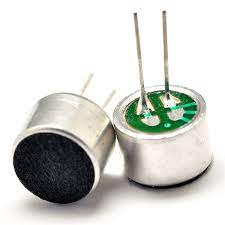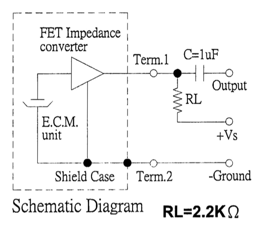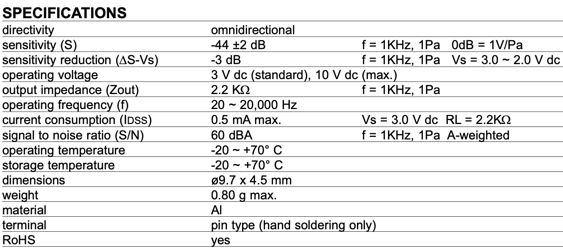

        Figure 2. Electret microphones are **polarized** two-terminal devices (ground is the right pin, connected to the case through the 3 green traces that look like fingers). [https://cdn-shop.adafruit.com/datasheets/CMA-4544PF-W.pdf](https://cdn-shop.adafruit.com/datasheets/CMA-4544PF-W.pdf) . 

The electret microphone sensor has extremely high impedance, thus it comes in an electrostatically shielded case with an integral FET follower lowering its impedance so it can pass current. Key specifications are operating voltage = 3Vdc, 10V maximum, at current $I_{DSS} \le 0.5mA$. 

## Arduino hardware & software interfaces

Connecting Arduino's 5V pin to Vs (in Fig. 2) should result in a DC voltage drop across RL = 4.7k$\Omega$ ~ 0.5mA * RL ~ 2.5V, leaving ~ 2.5V on "Term.1" (Terminal 1 of the microphone) in Fig. 2, which we can measure directly on Arduino's A0 without a coupling capacitor, as in Fig. 3.

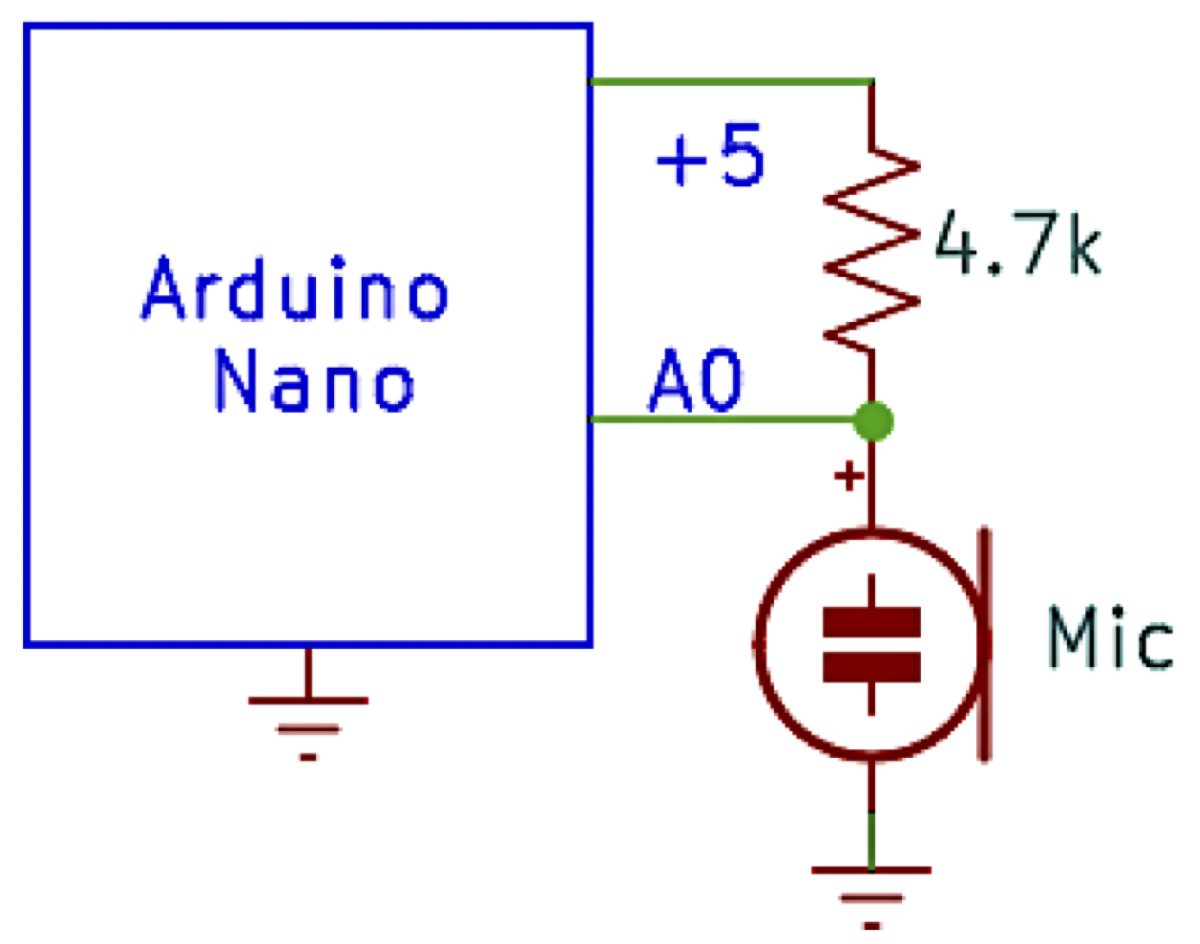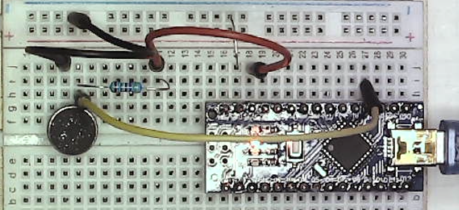

        Figure 3. Schematic and breadboard of a direct connection of the microphone to Arduino. RL =  4.7k.

Note and respect the polarity of the microphone pins.  [Footnote: Alternatively, the microphone could be connected to Arduino's 3V3 pin through R=2k. I expected 3.3V to be quieter, but in reality the 5V has *common mode* noise (with Vref), so the microphone signal is quieter when connected to 5V.] 

Arduino is programmed with `oscope1.ino`, as described in the previous chapter. 

## MATLAB data interface: oscope2.m

Launch `>> oscope1` and debug it if it doesn't initialize and display a plausible signal on A0 when the run button is checked. It won't be a large signal, but should respond to shouting directly into the microphone (Figs. 3-4). Bugs will just get obscured and harder to find if you proceed making new changes to broken code or hardware. When lost on a hike, the best thing usually to do is to retrace your steps until you find familiar landmarks. Then move forward more carefully so next time you're less likely to misread the trail cues. Same with electronics -- when the @#$& system doesn't work, go back looking for a sign that things are working, and thus try to localize the fault between those points. 

We made `oscope1` as simple as possible to facilitate debugging. Now we want to make the following improvements: 

- Calibrate the time axis. 

- Make it automation-compatible.

- Improve error handling.

- Display the refresh or frame rate. 

To do this, `>> edit oscope1` and `Save As --> oscope2. ` Now the editor should have `oscope2` open for editing. (Keep the old, working `oscope1` to fall back to if/when the systems stops working. This is also known as "forking" in software development [4].) Replace `oscope2`'s code with Listing 1:

        Listing 1. oscope2.m code.

Examining what changed: 

1. `runBtn`'s `callback` is now `oscope2`. **DON'T FORGET THIS** ... I've wasted more time than I want to admit wondering why my new code doesn't work ... when the answer is that it simply isn't being called. `callback` is the code that gets executed when the button is pressed ... it won't matter what code is in `oscope2`, if clicking the button calls `oscope1!`

2. Edit the initialization of `ard` to match your operating system and your Arduino port, and make sure the baud rates are the same.

3. Arduino measured the duration of acquisition in microseconds, and appended it as two `uint16` words after the 800 A0/A1 values. To  calibrate the horizontal axis, the `plot` function was replaced with three lines: 

I hope you're appreciating MATLAB's expressiveness and efficiency. 

4. `oscope1`  can only be activated by a user clicking on a button, which can't be (easily) automated.  Adding a Boolean variable called `runOnce` creates a command-line trigger, so `>> runOnce = true; oscope2;` makes `oscope2` execute the `while` loop one time. `runOnce` is conditionally initialized following the initialization pattern of `runBtn` and `ard`. If true, MATLAB executes the `while` loop. The second to last line in the loop sets `runOnce = false;` so the loop only will only ... runOnce.

5. Infrequently `oscope1` generates an error on my system: 

Warnings don't stop MATLAB, but the next line or two typically throws an error and stops execution, because if insufficient data was read, `bin(802)` won't exist. This code tells MATLAB explicitly how to deal with an error (instead of stopping) using the `try/catch` construct. After sending a `'b' `to Arduino, we  `try` to process the data. Any error between `try` and `catch` results in execution jumping to the `catch` block: the serial buffer is flushed and a * is printed to subtly indicate an error occured. 

6. Quantifying performance is useful so let's display our oscilloscope's refresh frame rate -- how many waveforms does it display per second? I wrote such a function `displayfps` for my digital microscope company ([Etaluma](https://www.etaluma.com)) that manages a frame per second (fps) counter, and recycled its code here. Copy the function from the Appendix into a file and save it in your PATH. 

## Microphone data

Save and run >> oscope2 and you should see something like Figs 3-4.

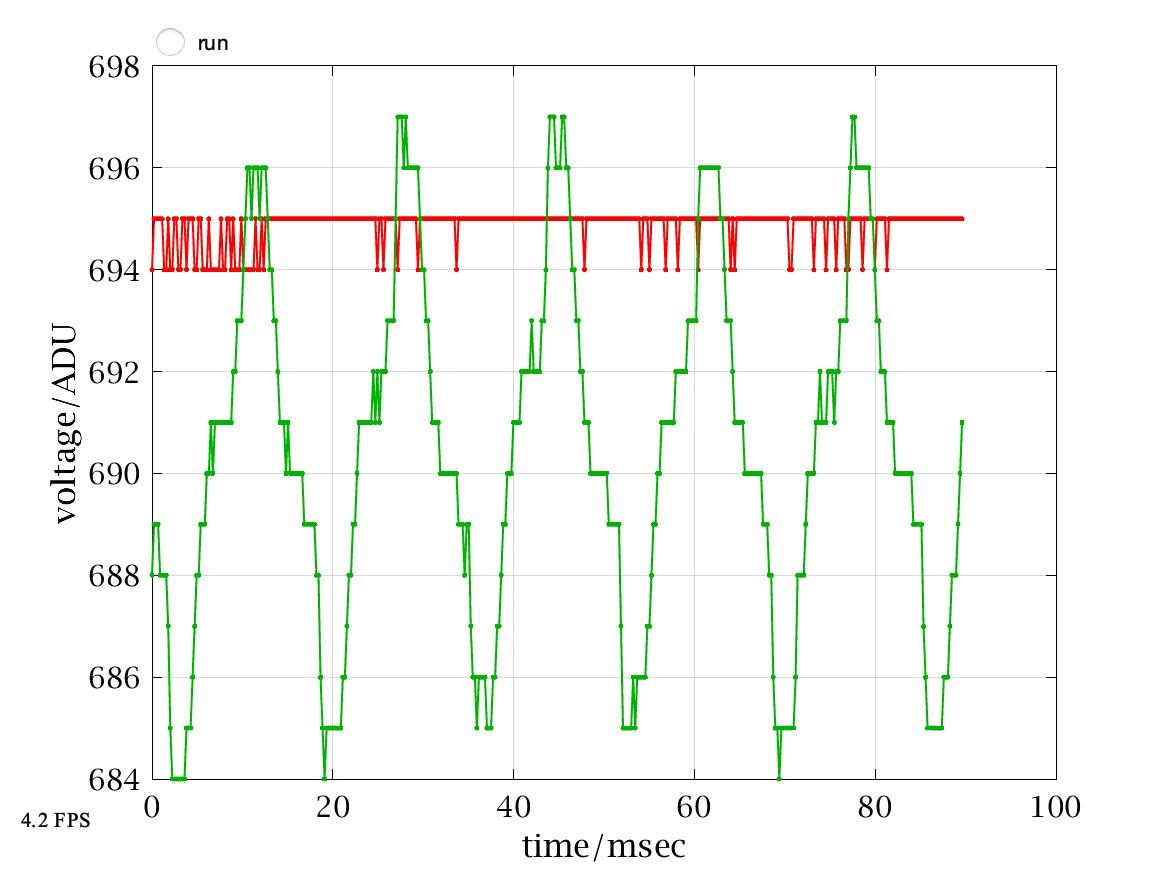

        Figure 4. Microphone output (red) and unconnected A1 (green). 

The room was fairly quiet, so the microphone signal flickered between 694-695 ADU. In volts: 

vref = 4.985; % volts measured on Arduino ref pin 3
mean(data) * vref / 1023

ans =     4.4001    4.4002


The DC level is a little more than the 2.5V we expected, meaning the microphone is drawing a little less than 0.5mA specified in the data sheet.  A1 may seem like a mystery -- what's the source of the signal, when nothing is connected? It's period ~17msec corresponds to a frequency of

1/17e-3

ans = 58.8235

or 60Hz. The high impedance "floating" A1 input is an antenna detecting electricity from ubiquitous power lines. Where AC power is 50Hz such as Europe, the period would be exactly 20msec. Consider how much harder it might have been to recognize 60Hz if the x-axis were in units of samples. Grounding A1 or jumpering it to A0 should remove the 60Hz noise. Looking at noise isn't so interesting, so start talking or singing with the run button on, e.g., 

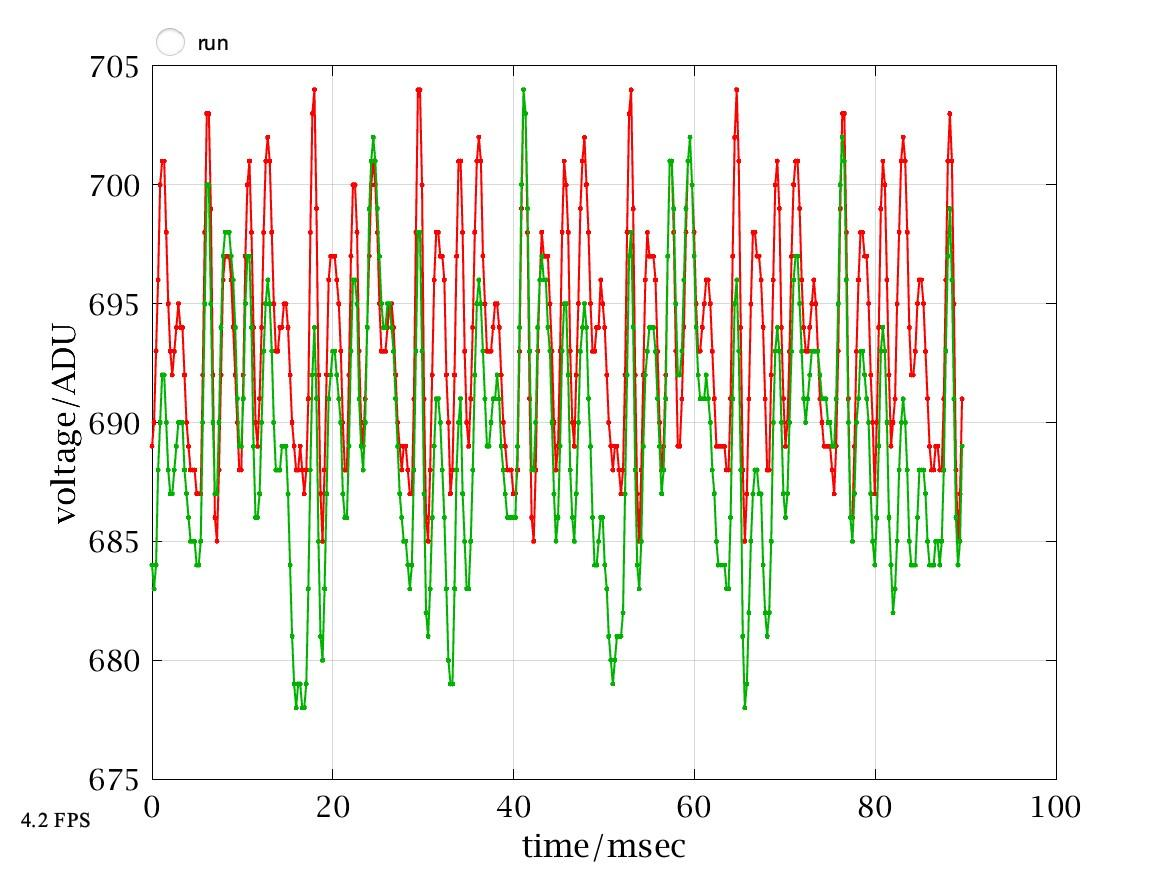

     Figure 5. Shouting into the microphone from inches away. 

Explore how this signal is related to your voice by varying your amplitude, pitch, tone. Also explore how geometry affects the signal -- distance and direction between you and the microphone. This signal's fundamental frequency is ~7 periods/80msec ~ 85Hz, near the F2 key on a piano. Floating A1 is copying or following A0, but note the 60Hz "modulation" is still there, producing "beats", a slow variation (modulation) most visible in the heights of the bottom green peaks that isn't present in A0. Multiple frequencies make complicated waveforms.

### AC Amplitudes

Let's quantify the signal's amplitude. The ups and downs average to zero so `mean` just gives the dc component. We can measure the peak-to-peak voltage using `max` and `min`, but that's quite sensitive to noise and outliers. 

vdata = data * vref / 1023; % in volts
max(vdata) - min(vdata) % peak-to-peak voltage

ans =     0.0341    0.0341


Root-mean-square (rms) is the standard measure of AC signal amplitude, and MATLAB has a built-in `rms` function, but for it to quantify just the AC signal, we have to first subtract the dc: 

rms(vdata) % includes dc

ans =     4.4001    4.4003


rms(vdata-mean(vdata)) % rms of the AC signal

ans =     0.0108    0.0107


$V_{rms}$ ~1/3 of $V_{pp}$ which is typical. For a pure sine wave where $V(t) = Asin(\omega t)$, $V_{pp} = 2A$ and $V_{rms} = A/\sqrt{2} \approx .707 A
$. Amplitude, peak-to-peak, and RMS are 3 common "units" to characterize AC signals, and you have to multiply by appropriate conversion factors when comparing signals in different units. 

### Amplification, SNR, and bias

The microphone's signal is quite small -- about 20 ADU peak-to-peak ~ 30 mVrms. Arduino's analog-to-digital converter (ADC) has at least ~ 1/2 ADU of noise so the signal/noise ratio (SNR) is at best ______ . I'll bet you wanted to divide signal (20 ADU) / noise (1/2ADU) for an answer of 40, but they're in different units! The 20 ADU was measured peak-to-peak, and an ADC has at least 1 ADU peak-to-peak error (±0.5 ADU both round to 0 so the peak-to-peak error for zero is ~1). Gotta be careful ... so SNR < 20 or worse that 5%. We can improve SNR by making the signal bigger -- amplifying it (and/or making the noise smaller).

A 20 ADU p-p signal could be amplified by a gain of 50 to fill the dynamic range (DNR) of Arduino's ADC (0-1023). But we'd have to change the DC level to make this work,. If we amplified the signal with its DC value ~700ADU by even 2 times it would saturate the ADC. Likewise, if we removed the DC entirely, then half the signal would be negative and would saturate (or damage) the ADC. Thus we need to *multiply just* the AC signal by 50 and *add* it to a DC offset (called "bias") = Vref/2, making the signal symmetrical between 0 and Vref volts = 0-1023 ADU. How to do that? With an op-amp circuit, as in Fig. 6.

## Op amp amplifier

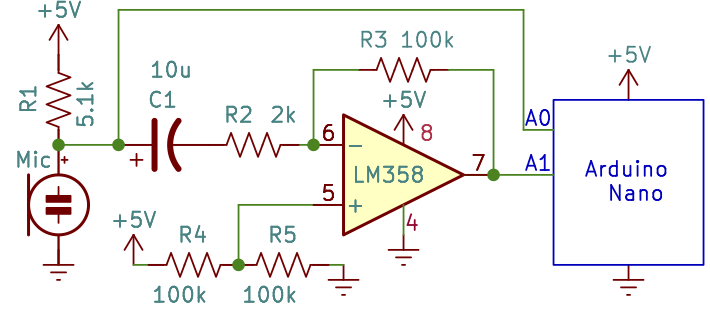 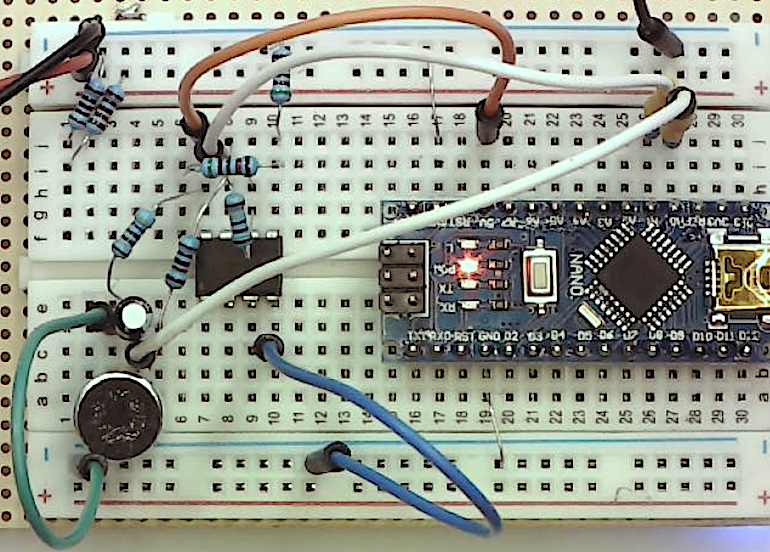

        Figure 6. Schematic and photo of amplified microphone. See below for component values. 

An inverting amplifier's gain = - feedback resistance/input resistance = -R3 / R2 in Fig. 6. With our limited selection of R's, we can achieve gain = 50 = 100k$\Omega$/2k$\Omega$. We've already selected R1= 5.1k$\Omega$. R4 and R5 are voltage dividers to set the bias voltage at Vcc/2 ~ 2.5V, so they just need to have equal value. No (significant) current flows into the op amp's + and - inputs, so a high value will reduce wasted power. 

We haven't explored filters yet, which is the quantitative context to design a value for the capacitor C1. Instead, I'll describe the "asymptotic" behavior in frequency space. C1's role is to block DC (0 Hz) but pass through audio frequencies (>~50 Hz). On the left side of C1 we expect a DC voltage ~ 3.1V (measured previously), and on the right side of C1 the dc voltage should be ~2.5V = Arduino's 5V * R5/(R4+R5). Not a big difference, but imagine if the DC input difference were amplified, the output would be 50*(2.5-3.1)V = -30V. So C1 allows the DC voltage of the negative input to equal the DC voltage of the positive input, and the amplified DC output is $-50(V_+ - V_-)$ = 0 volts DC *in addition to the bias voltage *of 2.5V. But any AC signals that pass through C1 appear at the output amplified (multipled) by negative 50. 

C1 has impedance `ZC1 = 1/(j*2*pi*f*C1)`, where `j = sqrt(-1)`, `f` is the frequency in Hz, and C1 is in Farads. ZC1 and R2 are voltage dividers for the microphone voltage, since the right side of R2 is (virtually) at a constant DC voltage by the op-amp's Golden Voltage Rule. If we choose C1 = 10uf, then the "corner" or "cut-off frequency" ([https://en.wikipedia.org/wiki/Cutoff_frequency](https://en.wikipedia.org/wiki/Cutoff_frequency)) where  `|ZC1| = R2` is 

R2 = 2e3; C1 = 10e-6;
fcorner = 1/(2*pi*R2*C1) % in Hz

fcorner = 7.9577

Audio frequencies (that humans can hear) are ~20Hz-20kHz, so at even the lowest audible frequency, the microphone signal's "gain" will be almost unity: |`R2/(R2+ZC1)` = 

abs(R2 / (R2+zc(C1,20)))

ans = 0.9292

Note that's different than using the absolute value of ZC in the voltage divider equation:

R2 / (R2+abs(zc(C1,20)))

ans = 0.7154

This is part of the art of using complex numbers ... "save `abs` for last". ZC's impedance is at "right angles" to R's impedance, so the total impedance, the denominator of the voltage divider equation, is not the sum of their magnitudes, but the vector sum -- the hypotenuse, which can be notably smaller. 

The last connections are to the Arduino -- let's measure the microphone output and its amplified version on A0 and A1 respectively. 

Common errors are incorrectly numbering the op amp pins, placing a device in an adjacent column of the breadboard, bad jumper wire, forgetting to ground the microphone, Nano, or op amp, or forgetting to connect top and bottom ground rows on the breadboard. What other mistakes challenged your debugging skills?? When working, the system  should display something like Fig. 7 in response to your (loud) voice: 

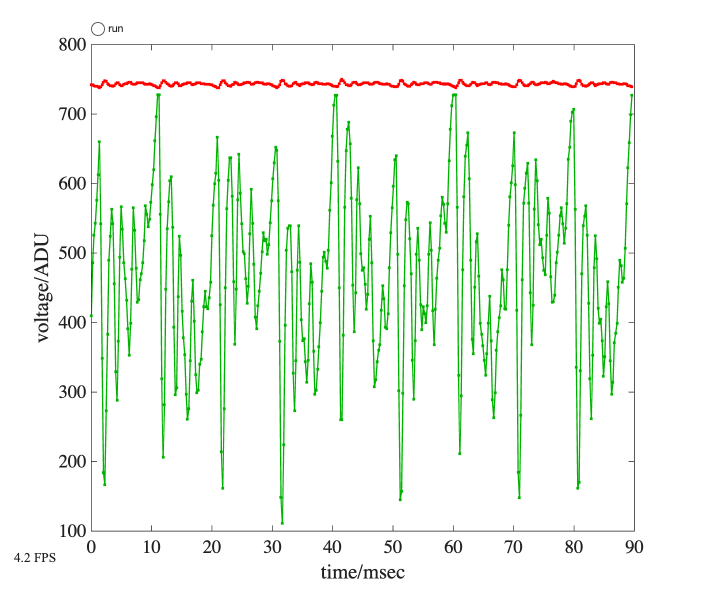

         Figure 7. Typical trace from oscope2 with the circuit in Fig. 6.

### Measuring Gain

 It's hard to see from Fig. 7 whether the green curve = -50 times the red one (ignoring DC). First, we can take the ratio of the two rms values as follows: 

rms(data - mean(data))

ans =     2.2760  123.9735


ans(2) / ans(1)

ans = 54.4698

That's within 10% of expectation, maybe not unreasonable since we didn't verify resistor values nor model more of the circuit's characteristics. Let's compare the waveforms:

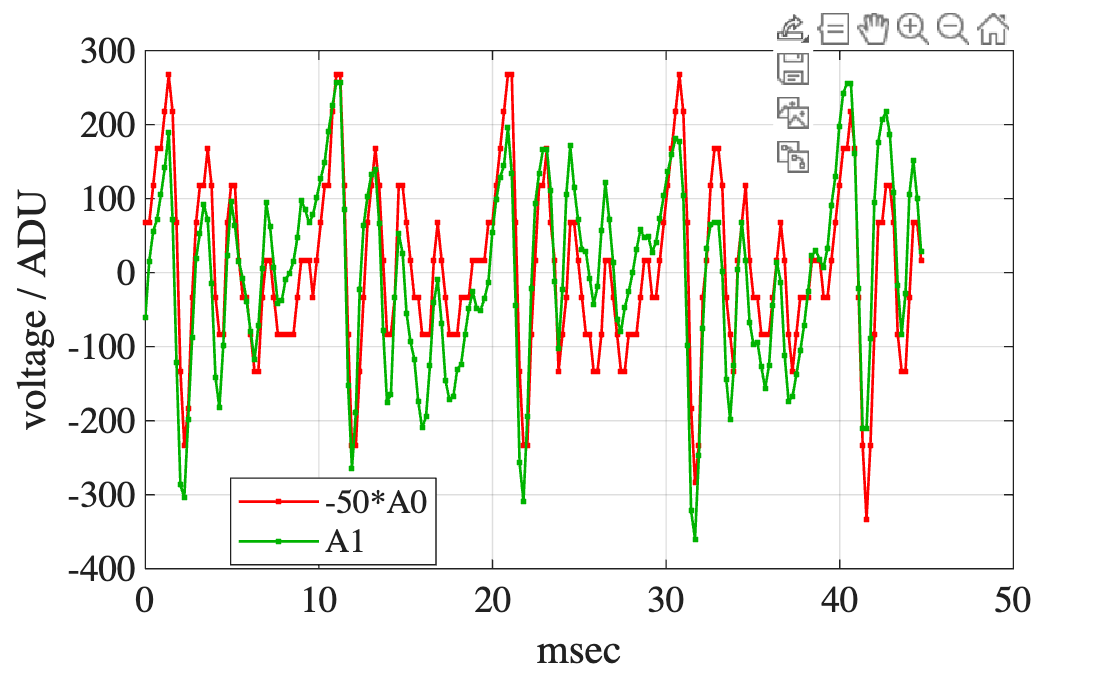

d2 = data - mean(data); % remove dc 
d2(:,1) = -50 * d2(:,1); % amplify
plot(t(1:200), d2(1:200,:), '.-');
xlabel('msec'); ylabel('voltage / ADU');
grid; legend(["-50*A0", "A1"])

        Figure 8. First half of Fig. 7, with dc removed and A0 multiplied by -50, the expected gain. 

I choose to plot half the data to view the individual measurements easier. There's no question that these two curves are highly correlated but not identical. A0 is clearly "blocky", exhibiting plateaus and jumps that are artifacts of the discrete ADC values, whereas these errors are much less pronounced in the amplified A1 data. A1 may show evidence of saturation or "clipping" that could explain an RMS ratio < 50. Repeating with a softer voice and/or greater distance between mouth and microphone could test that hypothesis. There is also a (systematic) phase or *time* *shift* between the two signals -- A1 is a little left of A0 -- which we'll explore in detail in future chapters.

### Frequency domain 

Modeling the subtle squiggles of complicated waveforms such as a voice through complex circuits like Fig. 6 is challenging. Again we could in principle integrate differential equations that follow the changing currents and voltages. Or solve the equations algebraically with complex impedances at each frequency using Fourier Analysis. MATLAB offers many functions and toolboxes for frequency domain analysis and most importantly, it "understands" complex algebra, so we don't have to worry about the mechanics. We'll spend the next couple of week learning to navigate this mathematical space, but for introduction, let's look at Fig. 7 data in the frequency domain -- which means instead of plotting voltage vs. time, plot voltage vs. frequency, using the Fourier transform to extract from Fig. 7 each frequency component's amplitude. Fig. 9 show half of the frequency domain data -- the amplitudes. The other half are phases, and in signals like this are seemingly random even though they contain key information about the signal. Decades ago I wrote a function I called `aspectrum` to visualize digital time series in the frequency domain. It requires the sample rate which we'll compute first:

help aspectrum

  function [s, f] = aspectrum(v,samplerate)
  compute amplitude spectrum of vector v or matrix v of
  column vectors. col vectors of d are spectral components.
  the second argument (optional) is the sample rate (Hz)
  and will plot the spectrum.  Phase in degrees.
  f is the frequency axis of the spectrum plot.



sr = length(data)/dt*1e6, % sample rate (#/sec)

sr = 4.4641e+03

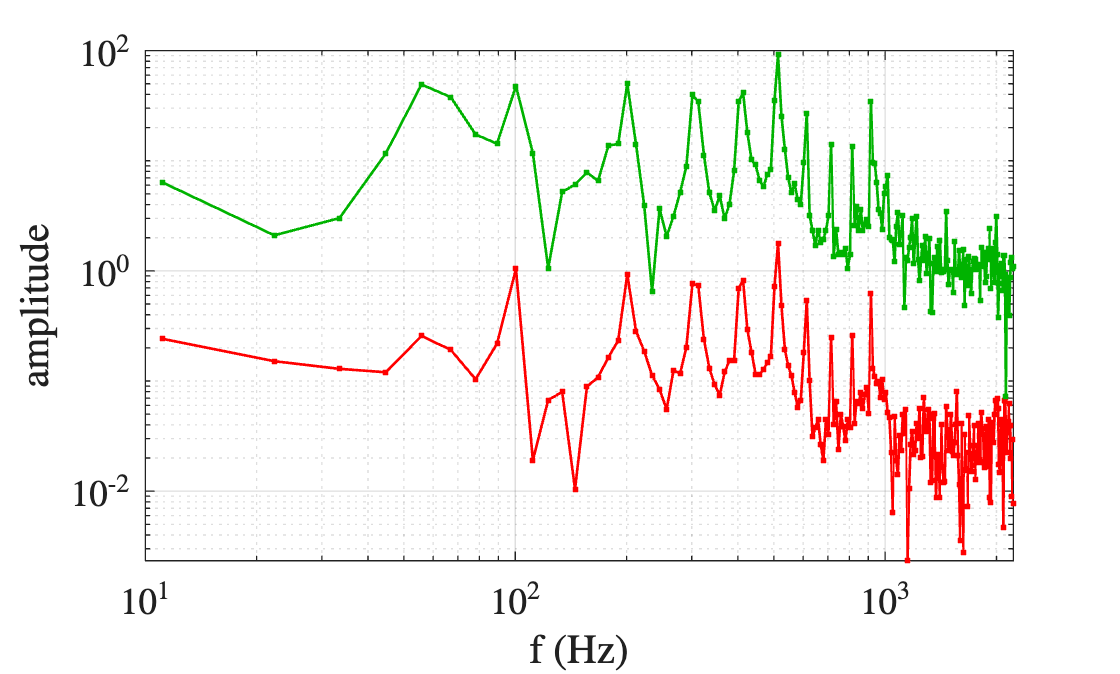

aspectrum(data, sr);

        Figure 9. Amplitude spectrum (in ADU) of Fig. 7, on log-log axes. 

Some key points: 

- The recorded signals consist mainly of a fundamental frequency $f_0$~100Hz and integer multiples of it, $nf_0$. The first harmonic = $1f_0$ is also the fundamental. 

- The broad bump below it is most likely 60Hz from ubiquitous AC electricity. 

- I don't recall what squeal I recorded that has around twice the amplitude at $5f_0$ as the lower harmonics. Usually amplitudes decrease with increasing frequency (because higher frequencies are higher energy), often odd harmonics dominate too, although not in this sound. Harmonic structure is nearly universal, due to geometrical resonances in our vocal cords and musical instruments. 

- The higher harmonics *appear* closer together because of the logarithmic x-axis scale. The 3rd and 4th harmonics have their energy "spread out" in adjacent frequency points. Sampling more than 400 data points would narrow the "frequency bins" and improve frequency and amplitude resolution.

- The gain of 50 is evident at these peaks, e.g., at *every *(lower) frequency, green/red ~ 50, until the unamplified signal reaches the "noise floor" ~f>1kHz. 

- Our $5 Arduino measured voltages on A0 and A1 *each* 4464 times per second!! Don't try to beat that with paper and pencil. Computers are way faster, but we are still smarter (so far).

### Real-time spectrum analysis

Spectrum analyzers are instruments that display signal amplitude (vertical) vs.signal frequency (horizontal). Generally expensive and exotic, we can make one by commenting 3 lines of `oscope2.m` and replacing them with:  

Note that I was tempted to be lazy, "this is temporary, so don't change `xlabel`, and do this in 2 lines". That can be really dangerous, even if just temporarily. We get side tracked, forget, even sometimes get run over by a bus, and our successors will be cursing us after spending hours sorting out such inconsistencies. So don't be so hurried when programming that you leave messes and traps behind. 

Save and click the run button, and explore how your voice looks in the frequency domain in "real time". During quiet moments, you can get a better measurement of the noise floor, e.g., 

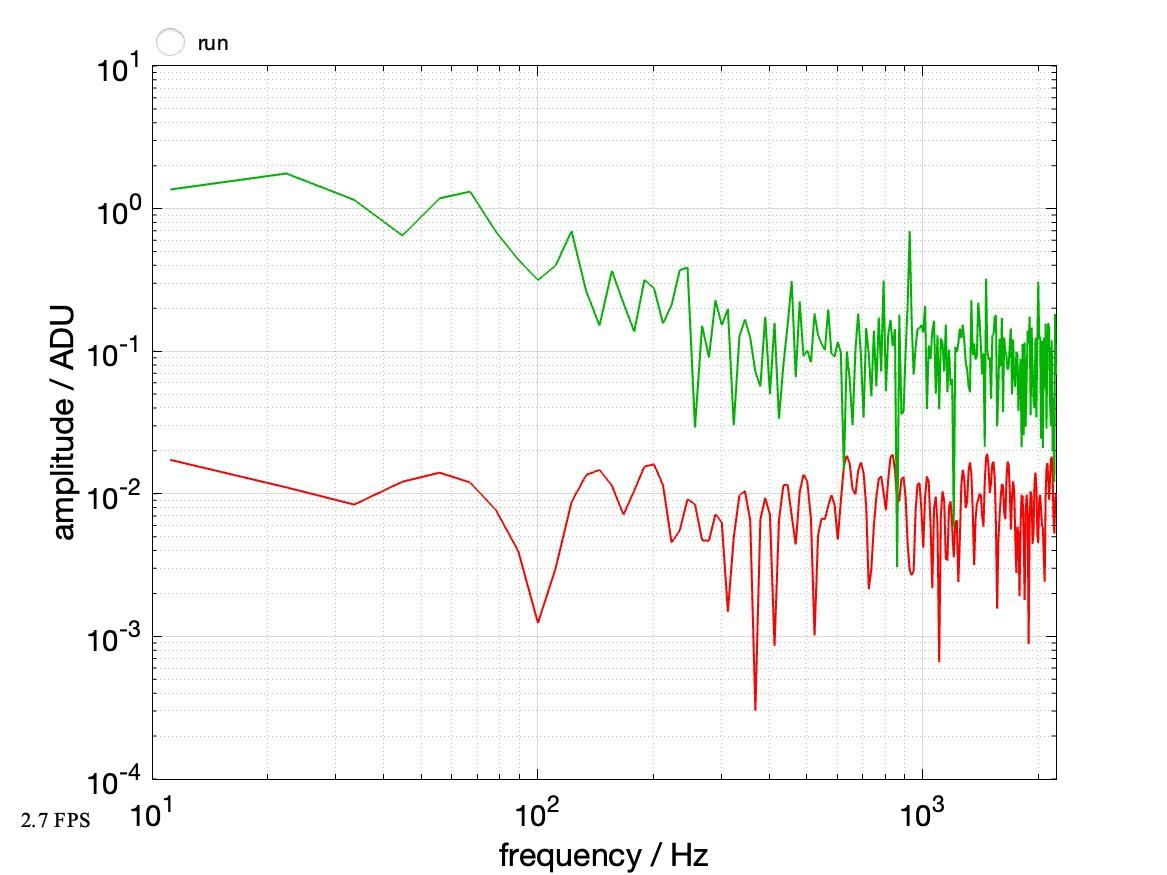

        Figure 10. Approximate "noise floor" spectrum with just evening crickets chirping ... 

The ratio of Fig. 9/Fig. 10 is an estimate of the Signal-to-noise ratio (SNR), which might be greatest at the highest peak ($5f_0$ ~ 510Hz): 92ADU/.2 = 460 (amplified), vs. (red) ~ 1.8/.015 = 180. Thus the op-amp circuit improved the SNR by ~4 times, not 50 times because it's also amplifying the noise. 

You might be wondering how noise could be so low as .015 ADU!? How is an integer ADU divisible by 100? That's one of the powers of Fourier analysis. Each frequency amplitude is computed by (weighted) averaging *every* time point, which can reduce noise by ~$\sqrt{N}$, the number of points. $\sqrt{400} = 20$, so

This ability to peer deep into data is empowering and enables designs of the amazing devices we love and use daily. Typically we'd start with a simpler signal than a voice -- maybe a sine wave of a single frequency that we can vary at will. That's what we'll build next, its called a "function generator".  

To better appreciate how signals relate to each other in time and frequency domains, see both at once using `subplot`: 

### Low frequency noise

You might notice some low frequency signals, such as in Fig. 11, the upward trend from 10-90msec. The "frequency" of this trend would be < 1/(2*90msec) ~ 5Hz, perhaps coming from a wind gust or elsewhere, but too low to be part of my voice. Replace C1 with a 0.1uf capacitor to shift the high pass corner frequency well above this noise. 

[NOTE: I think R2 had a larger value in the examples below.]

fcorner = 1/(2*pi*R2*.1e-6)

fcorner = 795.7747

 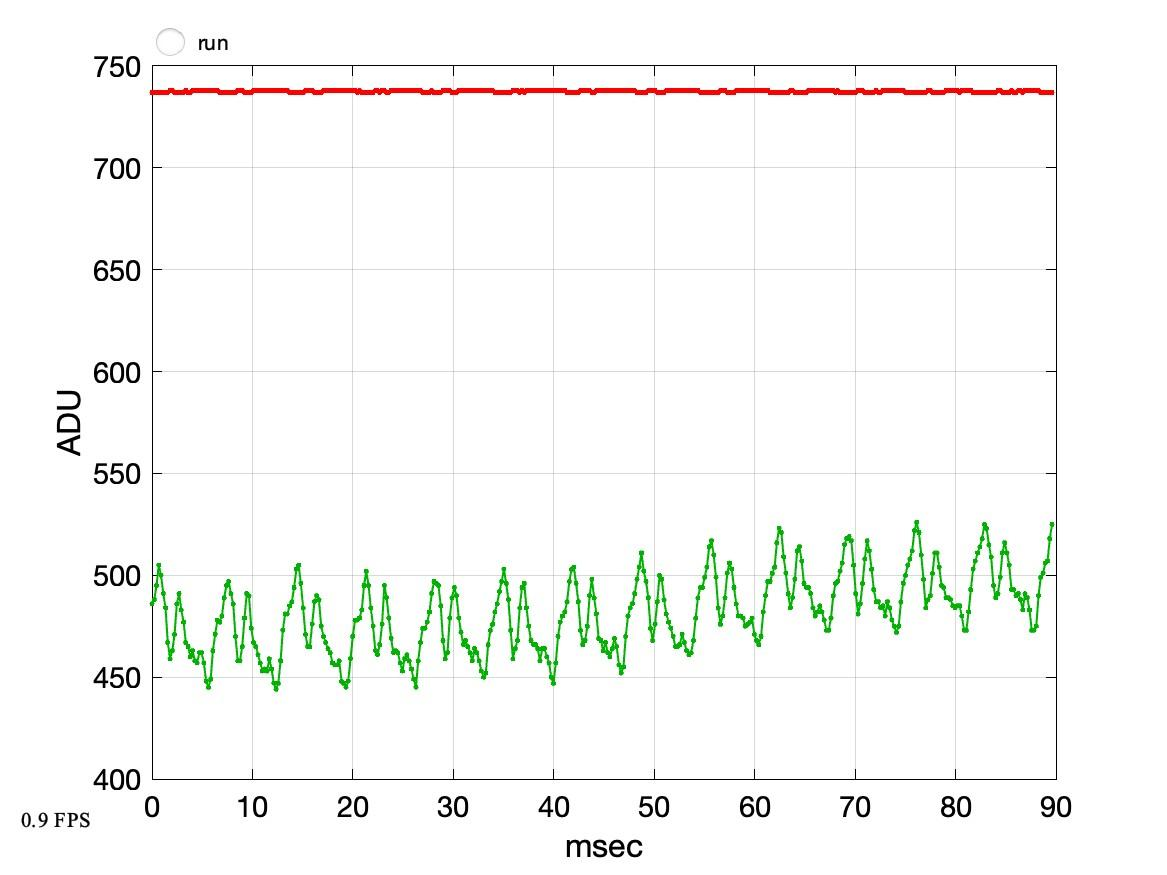

        Figure 11. Very low frequency noise appears as baseline drift in the time domain, can be attenuated/removed by changing C1 to 0.1uf.

Verify visually that there is less low frequency noise with C1=0.1uf, by observing a flatter baseline in the time domain or lower low frequency amplitudes on the left side of `aspectrum` plots. 

## Calibration and validation

Whenever you construct a new instrument, in this case your `oscope`, you shouldn't trust it blindly. How do you validate that its new results are trustworthy and accurate? Ideally you have another similar calibrated instrument to compare. For example, a DVM may come with a "Certificate of Calibration" stating how and when it was calibrated. In the USA, the National Institute of Standards and Technology (NIST) is the Federal agency that manages calibration standards -- that's where the world's standard for 1±<1e-9 VDC lives [5]. 

We didn't take our oscope to NIST, but instead looked for self-consistency at several levels. Did the waveforms and spectra respond to changes in input consistently and as expected -- loud voices correlate with higher amplitudes, higher pitches with peaks shifting rightward? Even better if you have a known calibrated input -- if you know the musical key of your voice or have a tuned (i.e., calibrated) musical instrument, then are the fundamental and harmonic frequencies where they should be? To calibrate whether the gain was 50, we used the `mrms` function to reduce a complex waveform to a single number, as our DVM does, and computed the ratio of amplified/unamplified. With the conversion factor 1023ADU = vref volts, we compared to DVM VAC measurements. With a fairly pure tone, we can compare the spectral amplitude with` sqrt(2)*mrms(data)`, to verify if `aspectrum` is measuring amplitude (peak). Try finding an online tone generator to verify the frequency.

In software, its also a good practice to write a routine to exercise and validate your programs. Some programmers suggest its best to write these first. A system isn't complete until its undergone some level of validation, and that level should be documented (and ideally automatable so its easy to run every time the system is changed). With validation documented, you can confidently assert that your oscope visualizes waveforms and spectra with correct amplitude and time or frequency scales. That's a significant achievement! Congratulations!

## Conclusions

Amplification multiplies a signal by a value greater than 1. If you need to reduce a signal or multiply it by <1, then two resistors configured as a voltage divider may do an exemplary job. But to get *more* signal than you start with requires an "active" component able to transfer energy from another power source in proportion to the input signal. A single transistor with collector and emitter resistors can do this, but op-amps are much more linear, versatile, easier to interface, can offer higher input impedance and lower output impedance, reject noise better, are inexpensive, etc. Very rarely if ever have I used transistors as voltage amplifiers, out of hundreds of times using op amps or a cousin of theirs called "instrumentation amps" (which are ideal for amplifying the difference between two voltages in real time, because their + and - inputs have the same impedances). 

Microphones are fun! Like most transducers (devices that turn one form of energy -- in this case pressure variations -- into another form -- electricity, AC voltage), their output tends to be weak. This is largely because of thermodynamic limitations -- there's no free lunch, there's not a lot of energy in a sound wave hitting the microphone, and energy tends to get lost (dissapate). That makes amplifiers ubiquitious with signal transduction and transmission. Op amps are powerful building blocks of amplifiers. With a few resistors you program gain, impedance, bias, offset, etc. As we further study AC and the frequency domain, you'll see how to add capacitors to create filters and frequency selective circuits. 

It's hard to imagine what this activity would have been like without the Arduino and MATLAB enabling us to visualize signals in the time domain and frequency domain. It's remarkable to think how the founding individuals of circuit theory -- Thevenin, Gauss, Kirchhoff, etc. didn't have such tools. I encourage you to spend as much time as you can using hardware oscilloscopes, spectrum and network analyzers, communication monitors, time domain reflectometers, lock-in amplifiers and other cool and exotic instruments that help us build correct intutitions and shatter erroneous preconceptions about this amazing world of electronics. 

## Appendix: zc.m

function [zc] = zc(farad, hz)
% function zc = zc(farad, hz)
% compute complex impedances of capacitor farad at frequencies hz
% hz can be a vector or matrix, and is persistent
    persistent hzz
    if nargin == 2, hzz = hz; end
    zc = 1 ./ (1j*2*pi*farad*hzz);
end

## Appendix: aspectrum.m

function [s, f] = aspectrum(v, sampleRate)
% function [s, f] = aspectrum(v, samplerate)
% compute amplitude spectrum of vector v or matrix v of
% column vectors. col vectors of v are spectral components.
% sampleRate (Hz) computes frequency vector and plots spectrum.  
    len = length(v(:,1));
    if len == 1, v = v'; len = length(v(:,1)); end
    fb = fft(v);
    s = 2 * abs(fb) / len;
    if nargin == 2  % display
      f = (1:floor(len / 2)-1)' * sampleRate / len; 
      s = s(2:floor(len/2),:);  % drop DC
      loglog(f, s); grid;
      xlabel('f (Hz)'); ylabel('amplitude');
    end
end

## Appendix: displayfps.m

function displayfps()
% count & display frame refresh rate
    persistent frame ttime lblFPS    
    if isempty(lblFPS) || ~isvalid(lblFPS) % initialize
        ttime = tic; frame = 0;
        lblFPS = uicontrol('Style','Text','String','0 FPS', ...
            'Tag','FPS','Units','normalized','Position', ...
            [.01  .05  .08  .03],'FontSize',10,'FontName','times');
        return;
    end    
    frame = frame + 1;
    if frame == 5 
        fps = 5 / toc(ttime);
        set(lblFPS,'String', sprintf('%2.1f FPS', fps));
        ttime = tic; frame = 0;
    end
end

## References

[1] Fourier analysis is discribed in differential equation textbooks and e.g., [https://en.wikipedia.org/wiki/Fourier_analysis.](https://en.wikipedia.org/wiki/Fourier_analysis.) A fascinating historical discussion is at [https://www.youtube.com/watch?v=nmgFG7PUHfo](https://www.youtube.com/watch?v=nmgFG7PUHfo)

[2] [https://en.wikipedia.org/wiki/Euler's_formula](https://en.wikipedia.org/wiki/Euler's_formula)  

[3] Horowitz and Hill The Art of Electronics, 3rd Ed. p. 225 ff.

[4] [https://en.wikipedia.org/wiki/Fork_(software_development)](https://en.wikipedia.org/wiki/Fork_(software_development)) 

[5] [https://www.nist.gov/news-events/news/2013/04/primary-voltage-standard-whole-world](https://www.nist.gov/news-events/news/2013/04/primary-voltage-standard-whole-world) 